# Optics and linearity

This scipt is designed to help you think about image formation and linearity.  Linearity is a very important part of conventional imaging systems, playing a role in how we think about many basic optics principles. 

To explore linearity, we consider a simple camera that does not even have a lens.  It only has a sensor whose aperture is covered by some scratchy glass.  Here is a picture of the rig.  For the stimulus, we consider a linear of LEDs.  Each one is a small point source, and we can control the intensity of the separate LEDs.

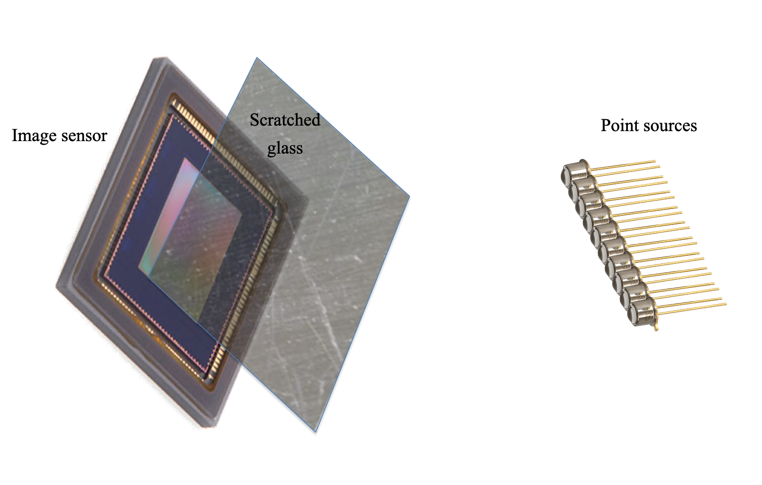

The question is this:  What can we learn from the sensor response about the intensity of the different point sources?  Even with this 'lensless' system.

### The lights and the sensor

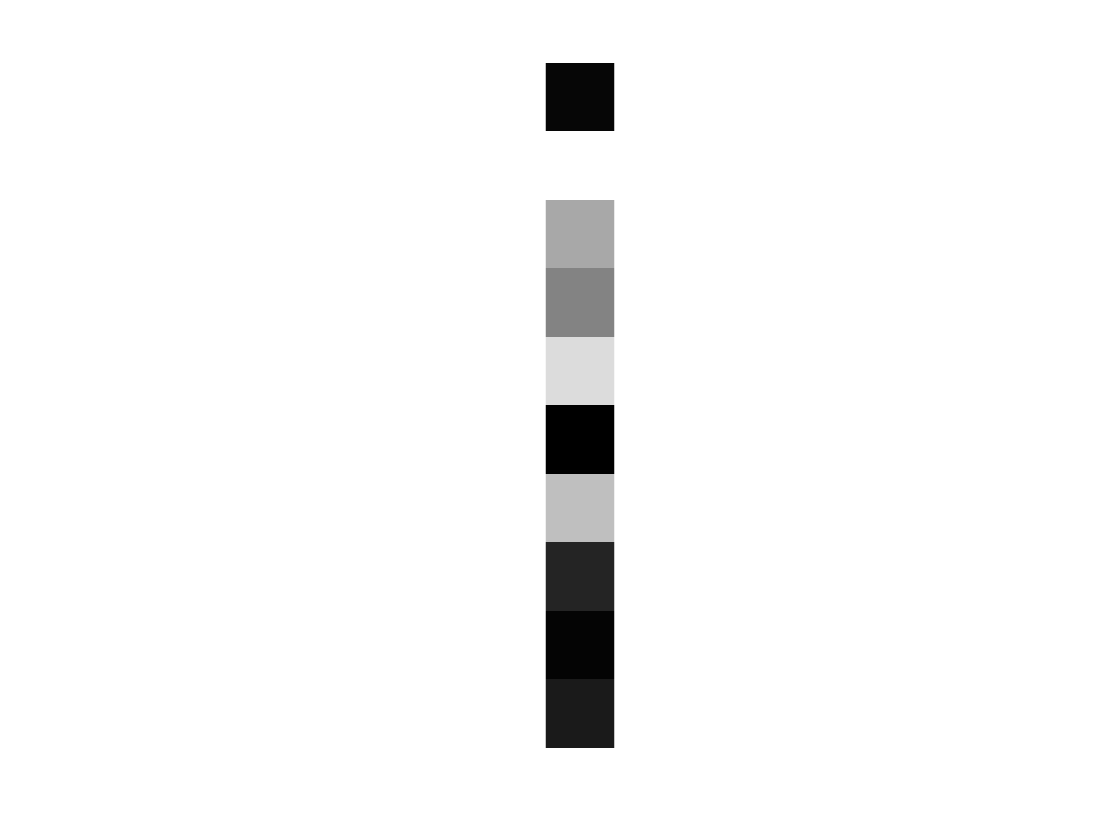

% Suppose the sensor has 64 rows and 64 columns
row = 64; col = 64;

% Let's start with just 10 LEDs in a line.
% We initalize their intensity randomly, between 0 and 1.
ledIntensities = rand(10,1);
nPnts = numel(ledIntensities);

% Here is an image of the LEDs
imagesc(ledIntensities); 
colormap("gray"); axis image; axis off;

### The sensor image for each LED

The image on the sensor will be a noisy mess, nothing recognizable.  The expected sensor response will pretty much be random noise, reflecting the scratches and absence of any focus.  The image from each of the different LEDs will also be different because they are coming from a different position in space.

We call the image from each of the LEDs their Point Spread Function (PSF).  There is a different PSF for each position.  We specify the PSF assuming we have an LED of 'unit' intensity.  You get to pick the unit.

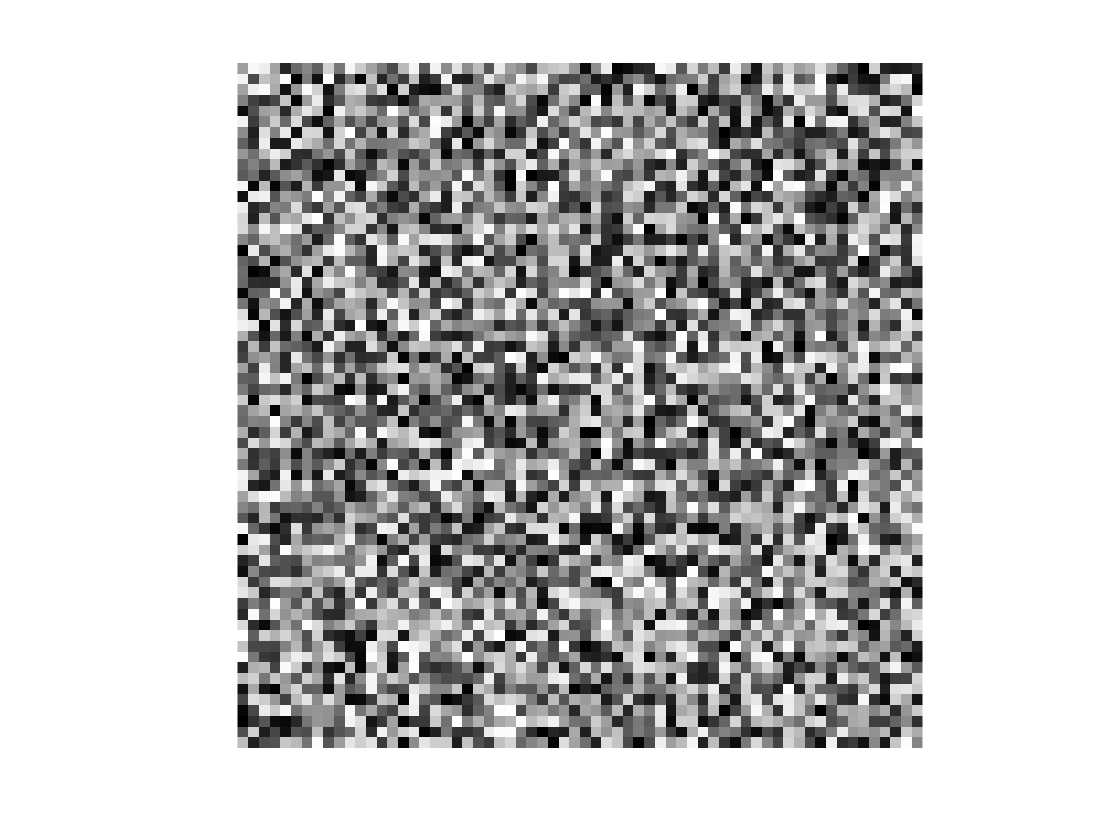

PSF = zeros(row,col,5);
for ii=1:nPnts
    PSF(:,:,ii) = rand(row,col,1);
end

% Here are the PSFs.  
for ii=1:nPnts
    imagesc(PSF(:,:,ii)); 
    colormap("gray"); axis image; axis off;
    pause(0.1);
end

### The whole image

Here are two important facts.  

- If we scale the intensity of an LED, the image is just a scaled version of its PSF. 

- The image formed by turning on two LEDs is equal to the sum of the images when we turn each one separately.  

Thus, we can calculate the expected image by adding up the individual PSFs, weighted by the led intensities.  It is convenient to calculate this sum using a matrix.  We 'vectorize' the PSFs, placing each PSF in the column of a matrix.

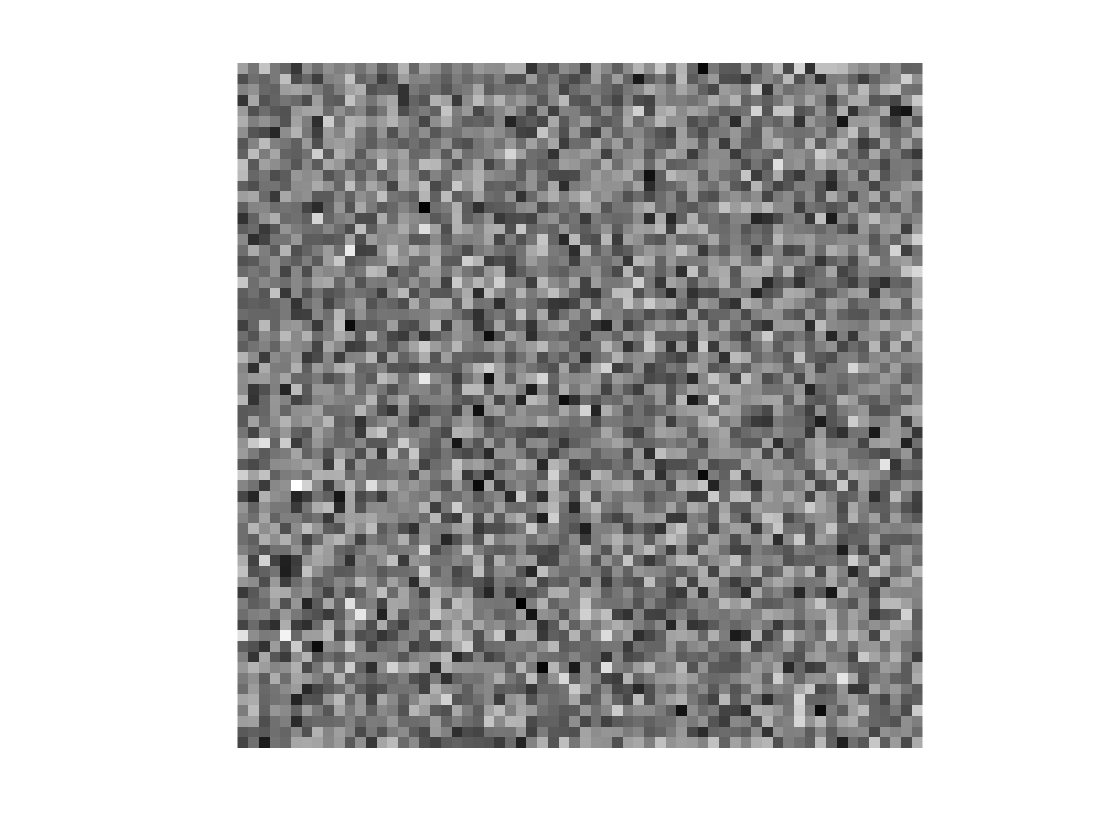

% Vectorizing the PSFs
vO = reshape(PSF,row*col,nPnts);

% Then we multiply each column by the intensity of its LED.
sensor = vO*ledIntensities(:);

% Here is what the image looks like.  (We have to reshape to see it as an
% image)
imagesc(reshape(sensor,row,col)); 
colormap("gray"); axis off; axis image;

### Estimate the input image from the output image.  

The equation for the sensor image is linear


$$sensor = \mathbf{vO}~ ledIntensities;$$


To estimate the led intensities from the sensor response, we only need to invert the equation.  The estimated LED intensities are returned this way.

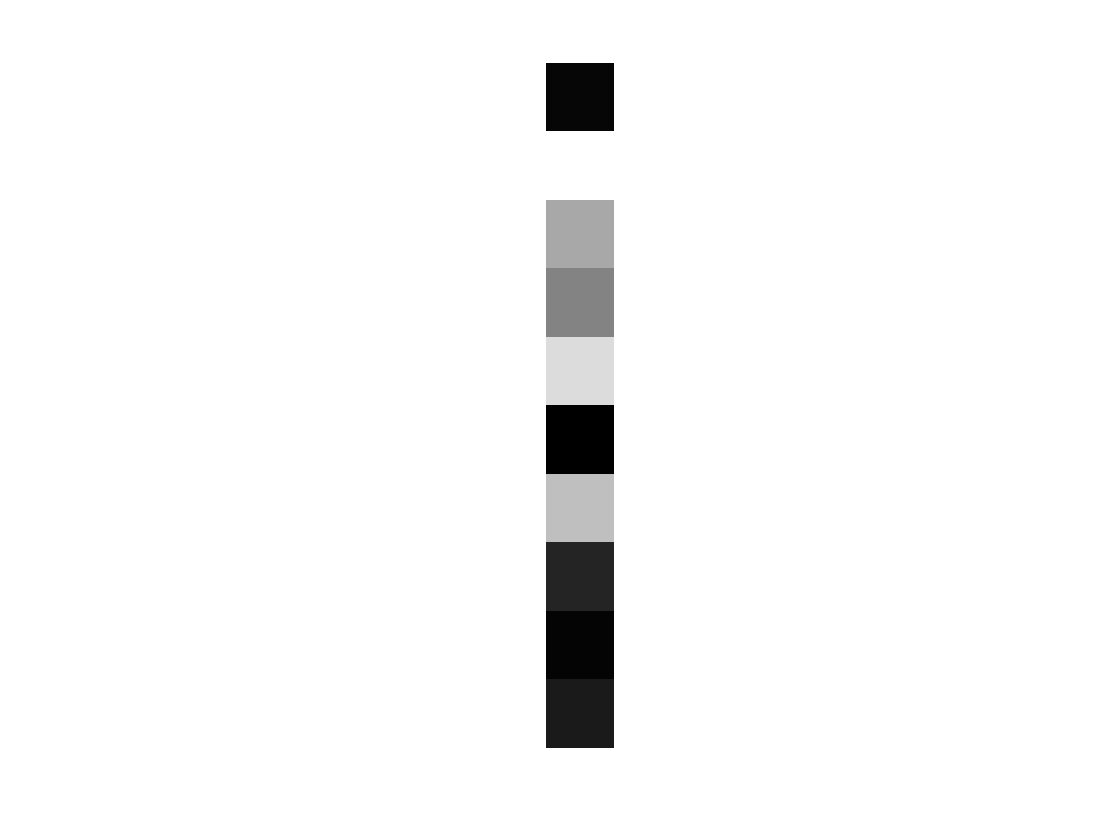

% This is Matlab's way of solving the linear equation.  It is equivalent to
% a pseudoinverse, which would like like this:
%
%      estLED = inv(vO'*vO)*(vO') sensor
%
estLED = vO\sensor;
imagesc(estLED);axis image; axis off;

### How did we do?

We can plot the estimated LED intensities and the true intensities

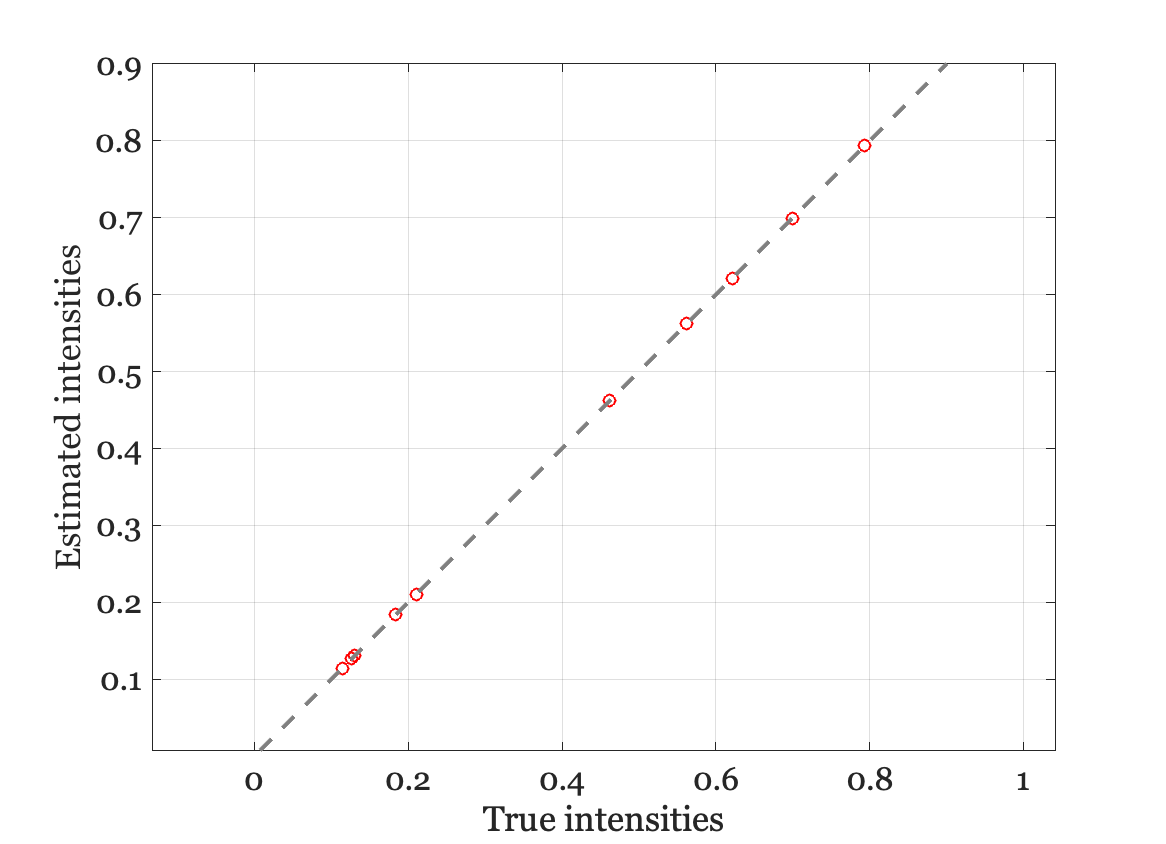

ieNewGraphWin;
plot(ledIntensities(:),estLED(:),'o');
xlabel('True intensities');
ylabel('Estimated intensities')
grid on; axis equal; identityLine;

### Let's scale it up

Suppose we have more LEDs so we can make a pattern.  Say 256.  Would the method still work?  Let's create a pattern of LEDs that form an image of an X.  We will make each of the intensities in the lines a little random, just to keep life interesting.

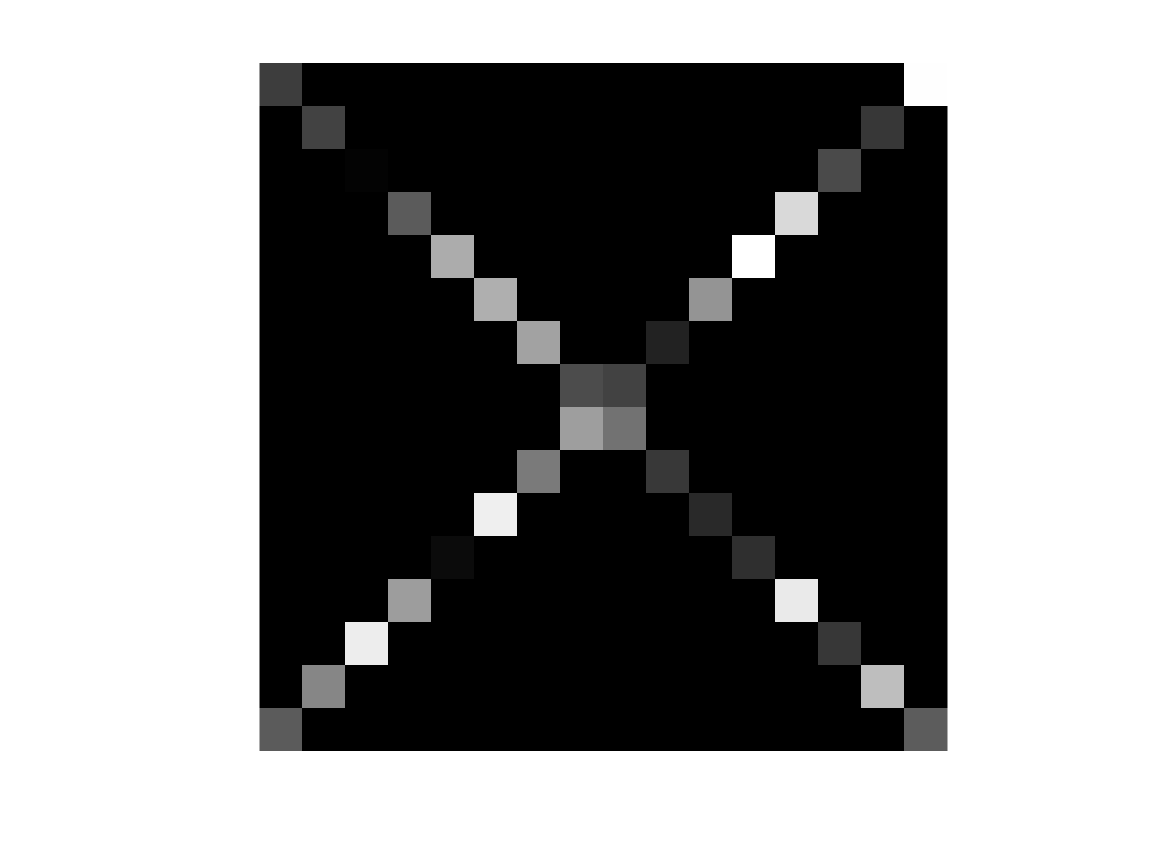

% The spatial array of the LEDs
ledIntensities = zeros(16,16);
nPnts = numel(ledIntensities);

% Make an X with random intensities
for ii=1:16, ledIntensities(ii,ii) = rand(1); end
for ii=1:16, ledIntensities(17-ii,ii)= rand(1); end
imagesc(ledIntensities); colormap("gray"); axis off; axis image;

We have more points, so we need more PSFs.  Let's make up some more.

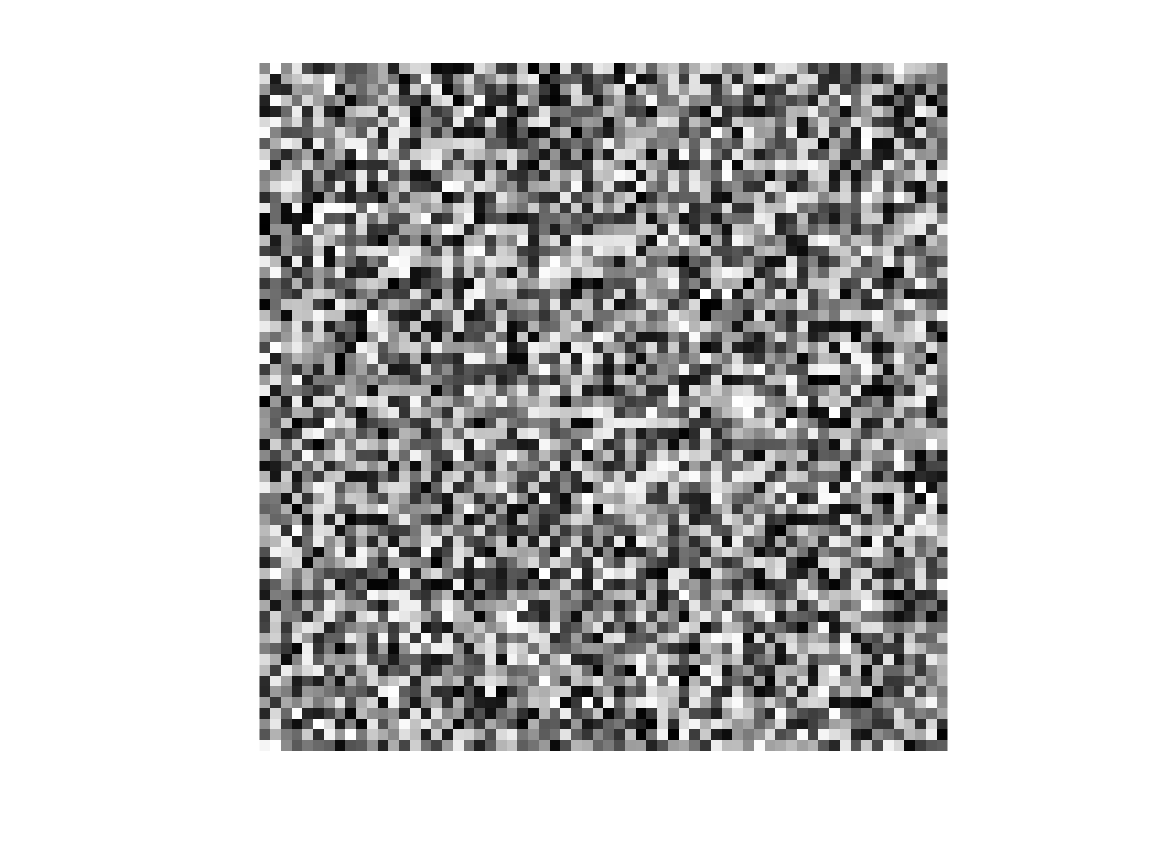

% Create some example PSFs
PSF = zeros(row,col,nPnts);
for ii=1:nPnts
    PSF(:,:,ii) = rand(row,col);
end

% Here are a few of the PSFs.  Random, again.
for ii=1:25:nPnts
    imagesc(PSF(:,:,ii)); 
    colormap("gray"); axis image; axis off;
    pause(0.1);
end

### Form the image and try to estimate

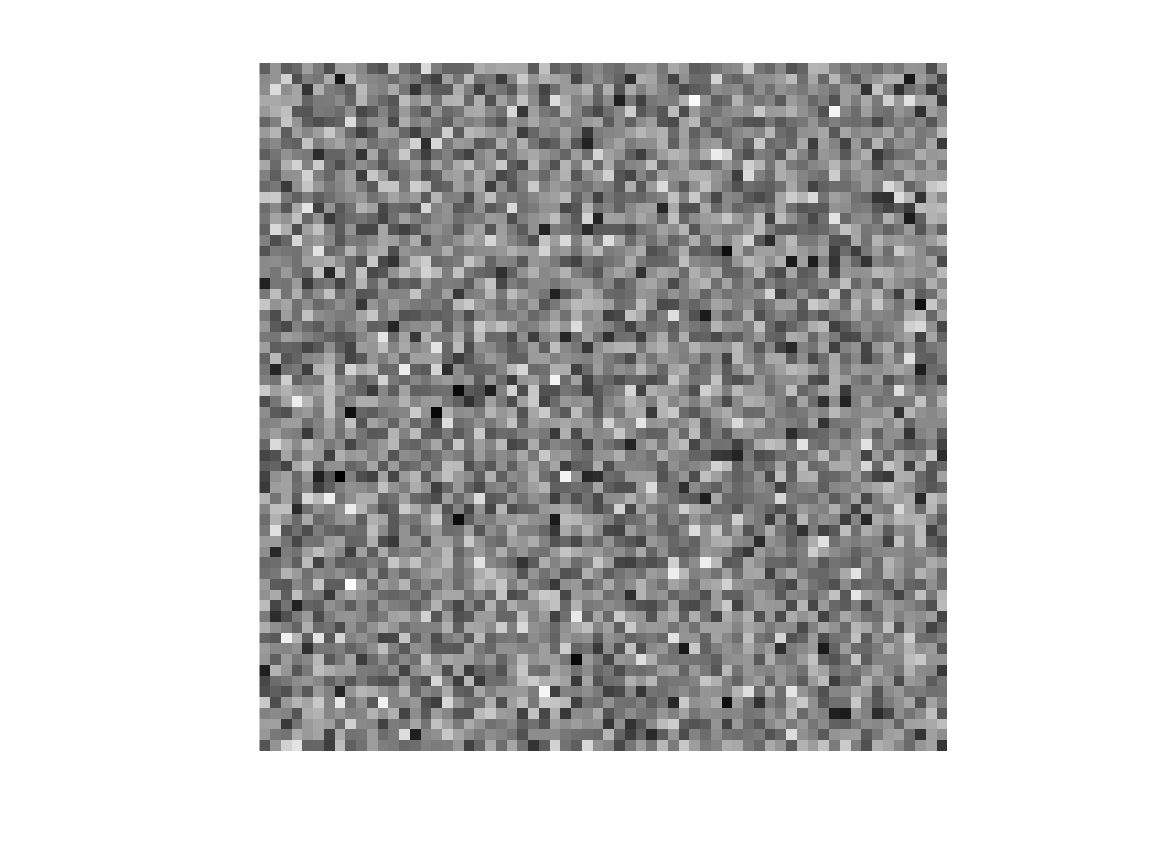

vO = reshape(PSF,row*col,nPnts);

% Then we multiply each column by the intensity of its LED.  We have to
% vectorize the LED intensities.
sensor = vO*ledIntensities(:);

% The sensor image.
imagesc(reshape(sensor,row,col)); 
colormap("gray"); axis off; axis image;


% The LED estimate
estLED = vO\sensor;
imagesc(reshape(estLED,16,16)); colormap(gray); axis image; axis off;

### How did we do?

A scatter plot of the estimated LED intensities and the true intensities falls along the identity line.  That's good!  

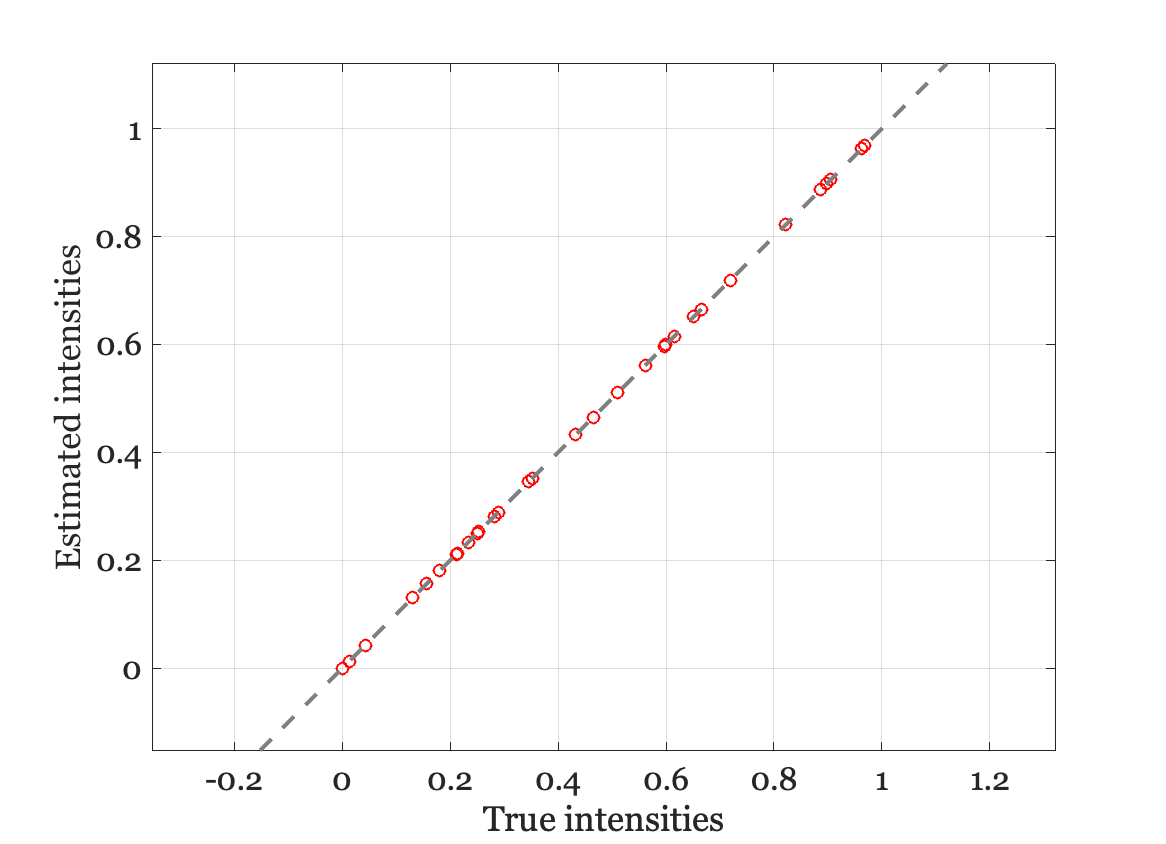

ieNewGraphWin;
plot(ledIntensities(:),estLED(:),'o');
xlabel('True intensities');
ylabel('Estimated intensities')
grid on; axis equal; identityLine;

Even though the image at the sensor looks like noise, we can recover the original image from it.  We just need to now each of the point spread functions of the LEDS.